## 1. Create a display object

clear all;
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.50);

## 2. Create a scene object for stimulus

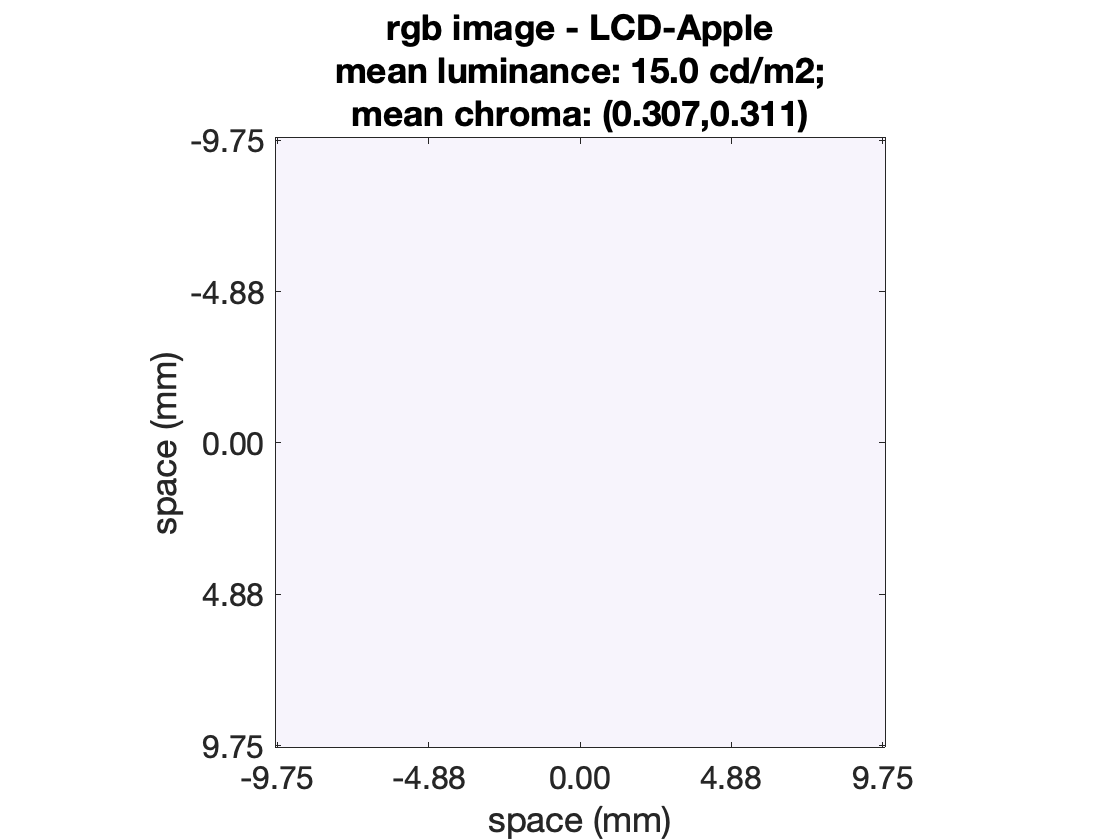

% specify stimulus parameters
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg',10, ... 
    'orientationDegs', 90, ...               
    'phaseDegs', 90, ...                    
    'sizeDegs', 0.5, ...                    
    'sigmaDegs', 0.25/3, ...                 
    'contrast', 0/100,...                  
    'meanLuminanceCdPerM2', 15, ...
    'center', [0 20], ...
    'pixelsAlongWidthDim', [], ...          
    'pixelsAlongHeightDim', [] ... 
    ); 
% compute the pixels that the stimulus will occupy

% % retrieve the display's pixel size 
% displayPixelSizeMeters = displayGet(presentationDisplay, 'sample spacing');
% % retrieve the display's viewing distance
% viewingDistanceMeters = displayGet(presentationDisplay, 'distance');
% % compute pixel size in visual degrees
% displayPixelSizeDegrees = ...
%     2 * atand(0.5*displayPixelSizeMeters/viewingDistanceMeters);
% % divide the stimulus size in degrees by the pixel size in degrees to get 
% % the number of stimulus pixels
% stimParams.pixelsAlongWidthDim = ...
%     round(stimParams.sizeDegs/displayPixelSizeDegrees(1));
% stimParams.pixelsAlongHeightDim = ...
%     round(stimParams.sizeDegs/displayPixelSizeDegrees(2));
% 
% % generate the scene
% scene = generateGaborScene('stimParams', stimParams);
% % Place the scene at the same distance as the display
% scene = sceneSet(scene, 'distance', viewingDistanceMeters);
% % Give the scene a name
% scene = sceneSet(scene, 'name', 'GABOR SCENE');
% 
% % visualizing the scene
% visualizeScene(scene);
scene = generateGaborSceneCustomize(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay, ...
    'minimumPixelsPerHalfPeriod', 10);

% Visualize the generated scene
visualizeScene(scene, ...
    'displayRadianceMaps', false);

## 3. Creating the scene on display

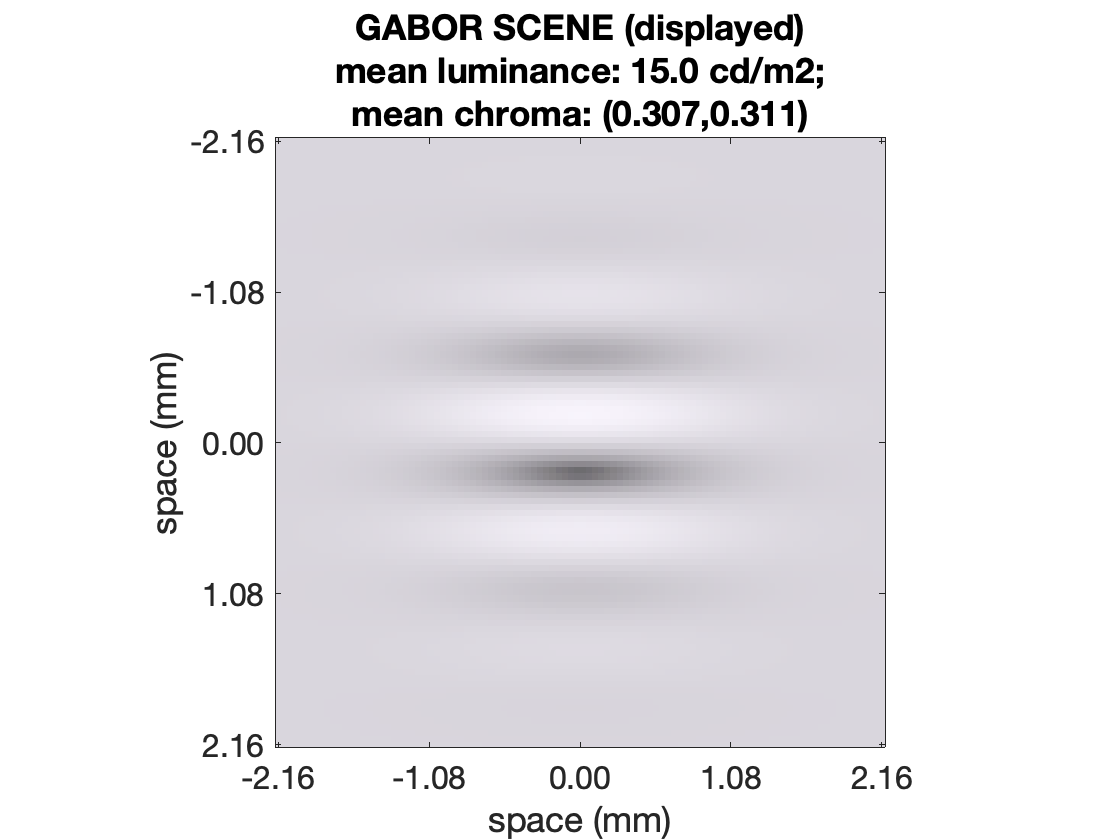

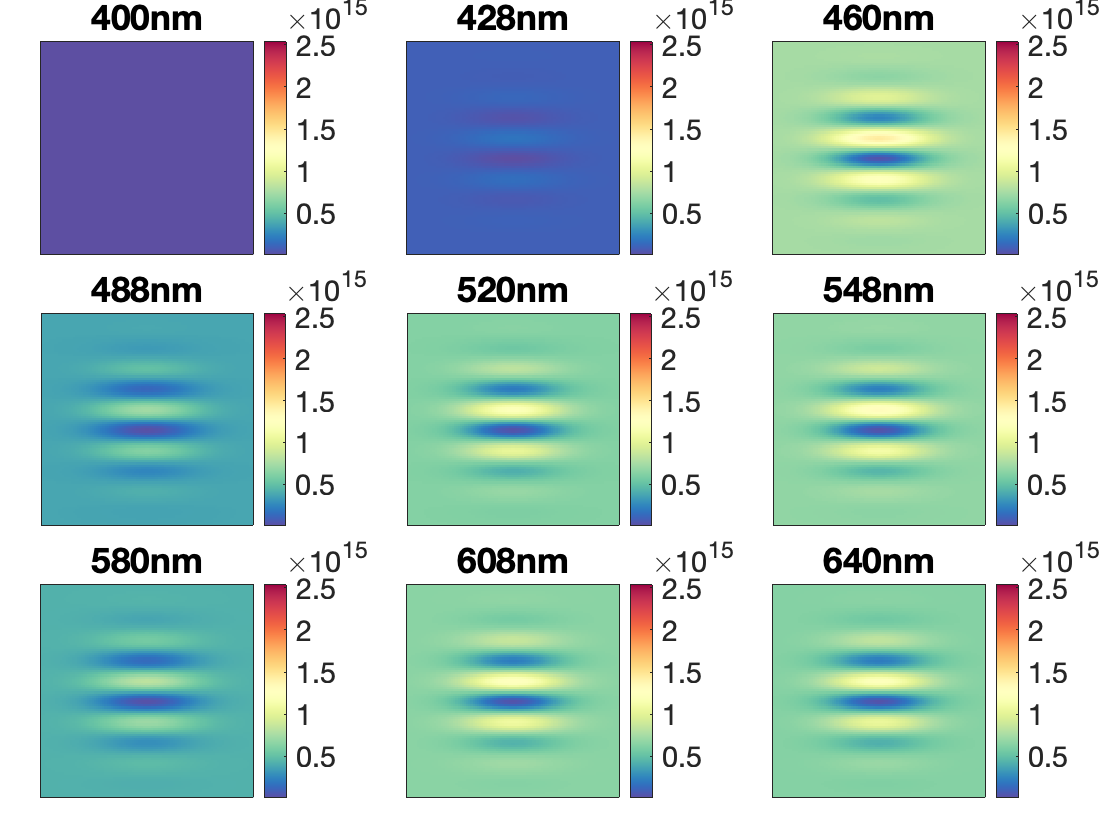

% Convert the idealized stimulus scene into a scene that represents 
% the stimulus as realized by the presentation display
displayedScene = realizeSceneOnDisplay(scene, presentationDisplay);
% Give the scene a name
displayedScene = sceneSet(displayedScene, 'name', 'GABOR SCENE (displayed)');

% visualizing the display scene
visualizeScene(displayedScene);

## 4. Creating Optical Image object for human

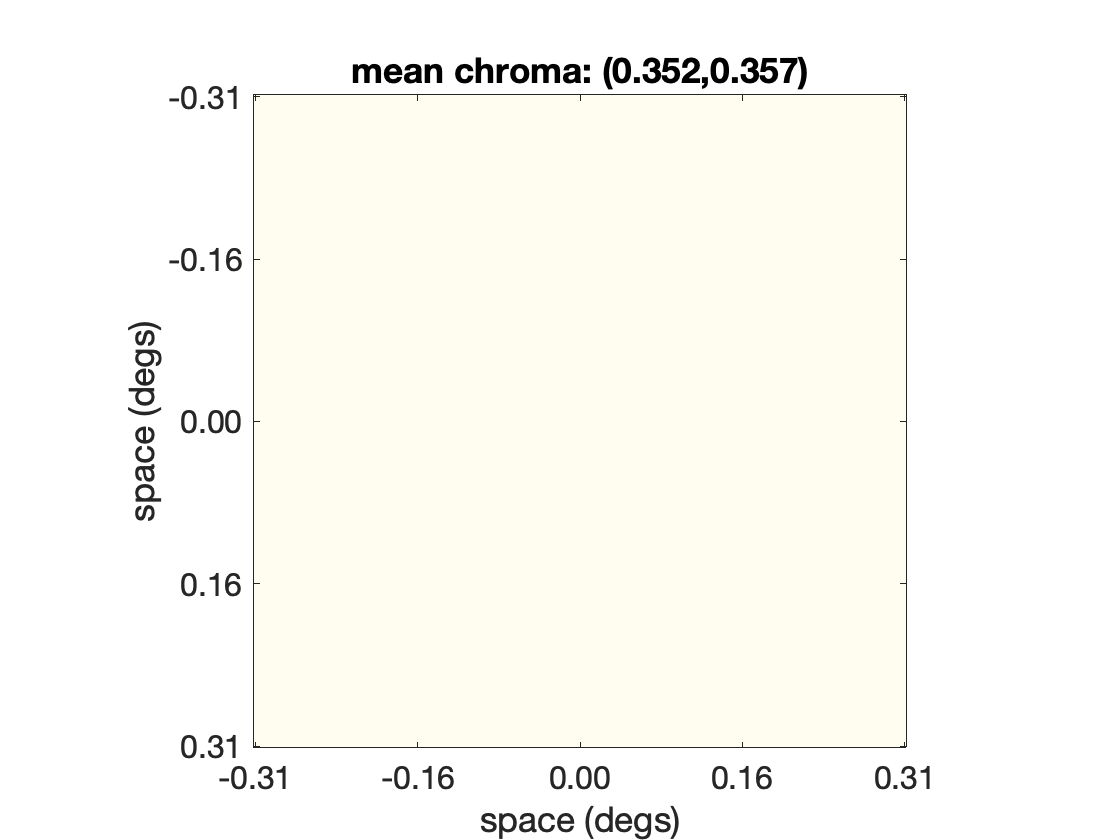

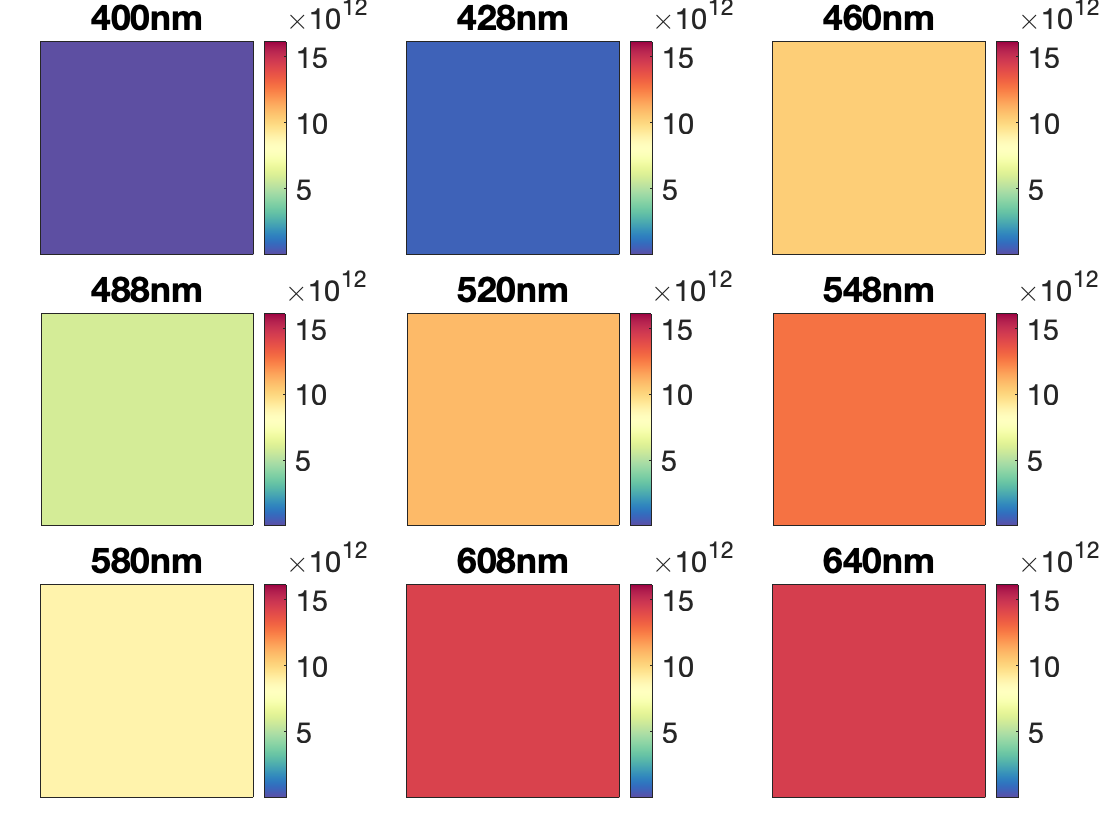

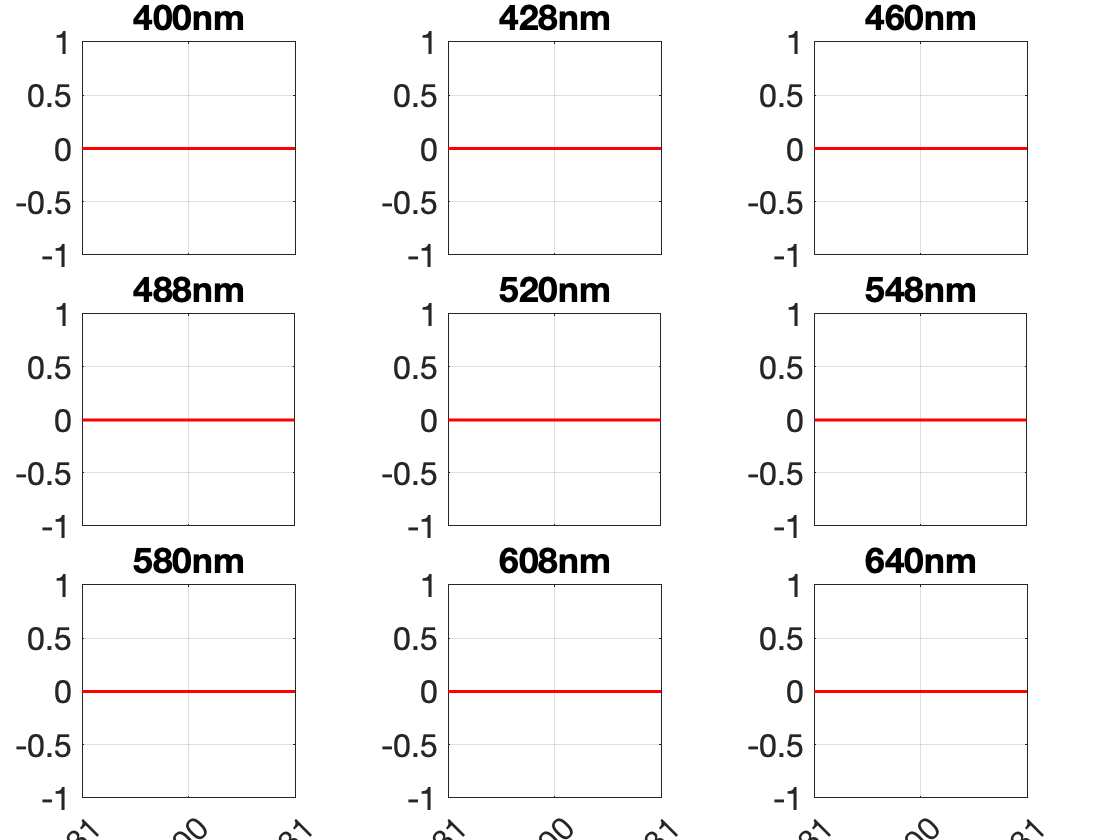

% Generate wavefront-aberration derived human optics
testOI = oiCreate('wvf human');

% % Visualize the PSFs and OTFs
% testSpatialSupportArcMin = 6;
% testSpatialSfrequencyCPD = 120;
% 
% % Visualize the PSF/OTF at 550 (in-focus)
% visualizeOptics(testOI, 550, testSpatialSupportArcMin, testSpatialSfrequencyCPD);
% % Visualize the PSF/OTF at and at 500 nm
% visualizeOptics(testOI, 500, testSpatialSupportArcMin, testSpatialSfrequencyCPD);
% Compute the retinal image
testOI = oiCompute(testOI, scene); % displayedScene

% Visualize different aspects of the computed optical image
visualizeOpticalImage(testOI, 'displayRetinalContrastProfiles', true);

## 4.1 Create OI - Skip all figures

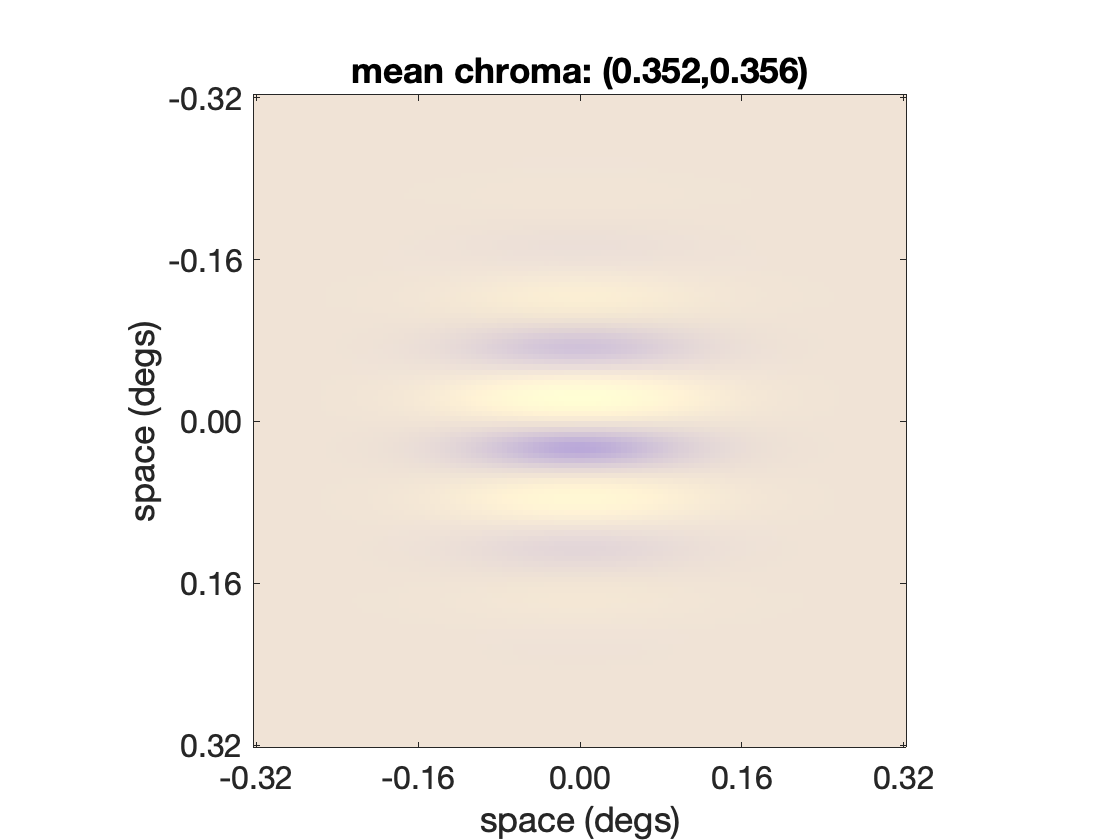

% Generate wavefront-aberration derived human optics
theOI = oiCreate('wvf human');

% Compute the retinal image of the test stimulus
OI = oiCompute(theOI, scene);

% Visualize the optical image of the test
visualizeOpticalImage(OI, ...
    'displayRadianceMaps', false);

## 5. Creating a Cone Mosaic object and visualize the response

% Generate a hexagonal cone mosaic with ecc-based cone quantal efficiency
theMosaic = coneMosaicHex(5, ...              % hex lattice sampling factor
   'fovDegs', [1 1] * stimParams.sizeDegs, ...        % match mosaic width to stimulus size
   'integrationTime', 15/1000);        % terminate iterative lattice adjustment after 50 iterations


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 648
Scones after making an S-cone free central patch: 443 (added Lcones:136, added Mcones:69)
Scones after pass 1: 273 (added Lcones:152, added Mcones:76)
Scones after pass 2: 197 (added Lcones:58, added Mcones:32)
Scones after pass 3: 182 (added Lcones:12, added Mcones:6)
Scones after pass 4: 178 (added Lcones:3, added Mcones:1)
Scones after pass 5: 178 (added Lcones:0, added Mcones:0)


## 6. Adding Eye Movement Info

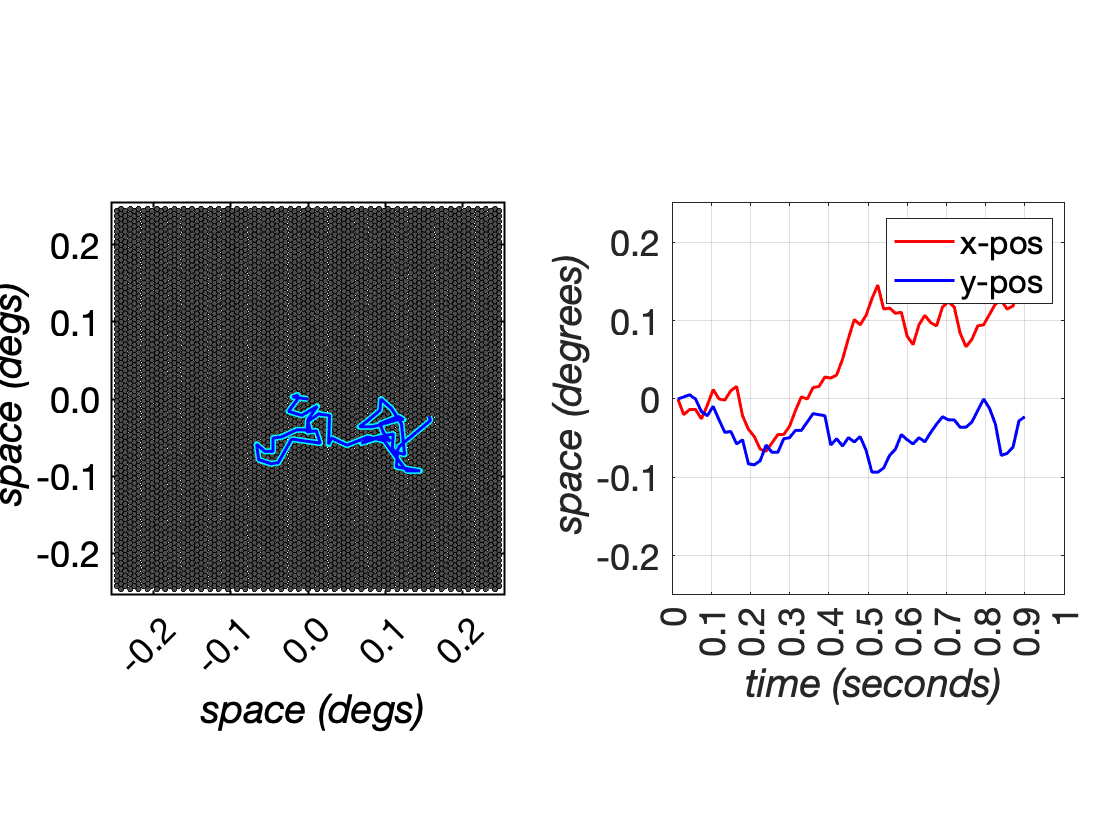

% Generate two instances of fixational eye eyemovements 
% each with 60 position samples. Given an integrationTime of 5 msec,
% this corresponds to a 60*5 = 300 msec long fixation
eyeMovementsNum = 60;
[emPaths, fixEMOBJ] = theMosaic.emGenSequence(eyeMovementsNum, 'nTrials', 2);

% Plot the first eye movement trajectory
visualizeConeMosaicAndEMPath(theMosaic, fixEMOBJ);

## 6.1 Optional - Create Zero Eye Movement Path

nTrialsNum = 2;
emPath = zeros(nTrialsNum, 60, 2);

## 7. Compute mosaic excitation responses

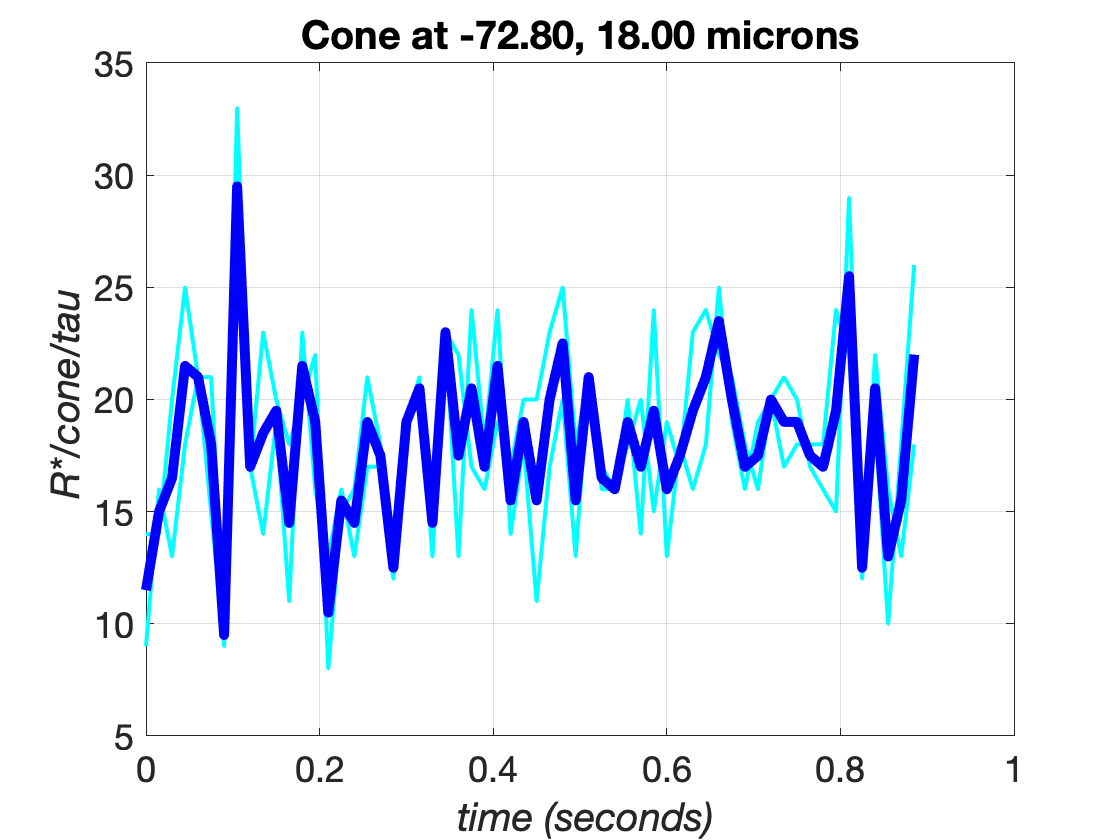

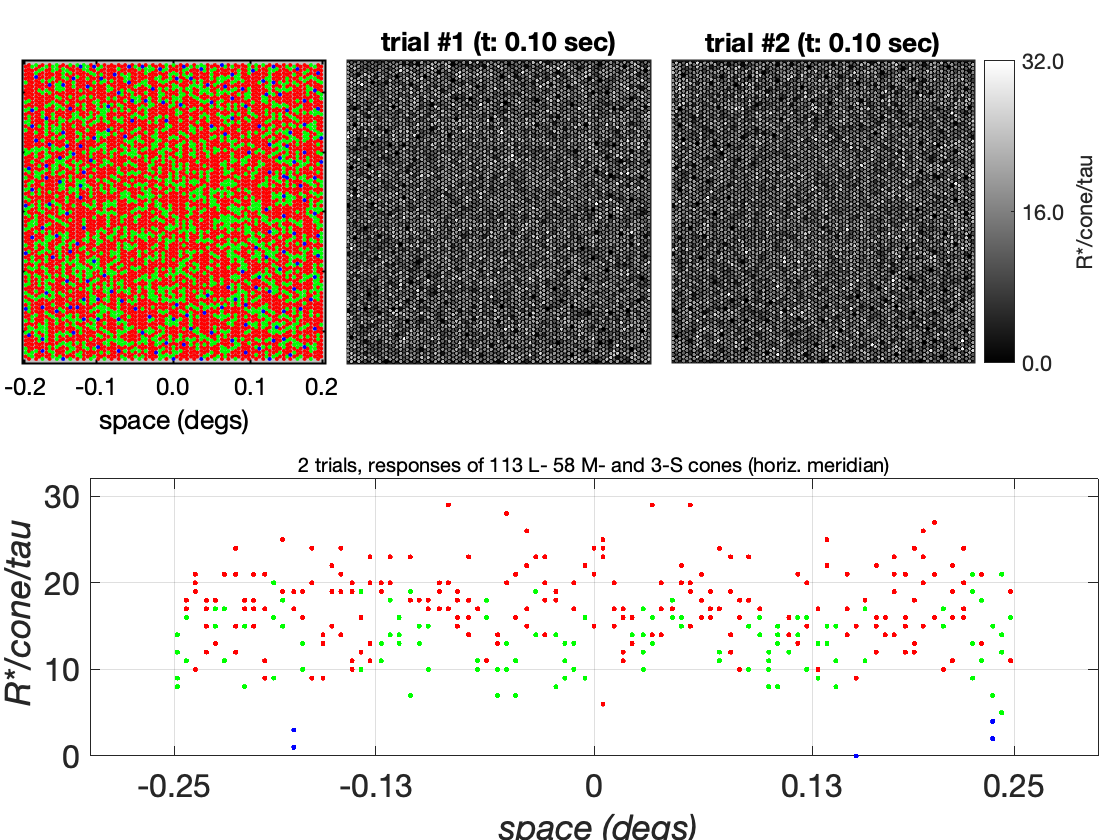

% Compute mosaic excitation responses
    % The first return is the noise free response (Poisson mean),
    % the second return is the noisy response samples
% [average, coneExcitations] = theMosaic.compute(testOI, 'nTrials', nTrialsNum);
coneExcitations = theMosaic.compute(testOI, 'emPath', emPath);
% coneExcitations = theMosaic.compute(theOI, 'nTrials', 10);
visualizeConeMosaicResponses(theMosaic, coneExcitations, 'R*/cone/tau');